# Project #1-1. HGU bearing PHM

- Name :       Hanminung,            Hwangseungeun

- student ID : 21800773                  21800805

- Detailed instruction : [https://github.com/ykkimhgu/digitaltwinNautomation-src/blob/main/HGU%20Bearing%20Dataset%20Description.md](https://github.com/ykkimhgu/digitaltwinNautomation-src/blob/main/HGU%20Bearing%20Dataset%20Description.md)

- Mechanical and Control Engineering

- 2023 Spring semester

## Bearing specification

- D1 = 37.05

- D2 = 24.95

- # of ball in bearing = 13

- Beta = 6.05

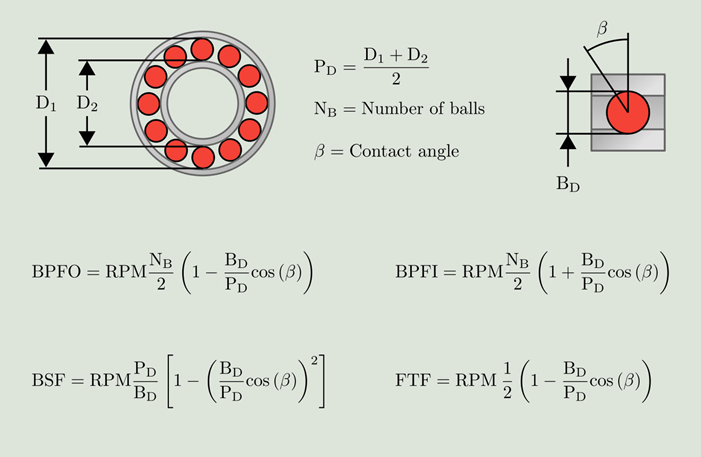

clear

addpath('Functions');
addpath('dataset');       % For dataset

## Load data

- Inner, Outer race fault size : diameter 1mm, depth 2.3mm

- Ball fault size : diameter 1mm, depth 1mm

- 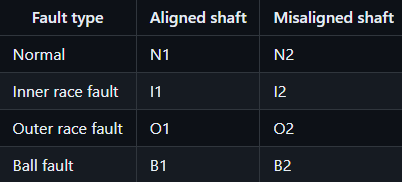

- Used a window a size of 12000, 1000 strides for data augmentation.

- 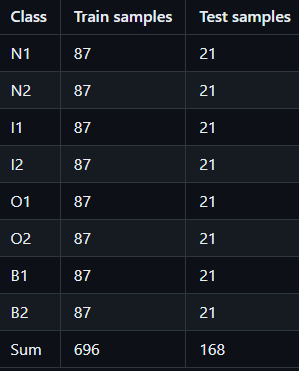

load('HGU_bearing_dataset_v1.mat');

fs = 12000;
rotFreq = 8.3333;

## Saving data

% trainAN = HGU_bearing_dataset_v1.trainset.N1;           save('trainAN.mat','trainAN');      % Align normal trainset
% trainAI = HGU_bearing_dataset_v1.trainset.I1;           save('trainAI.mat','trainAI');      % Align inner trainset
% trainAO = HGU_bearing_dataset_v1.trainset.O1;           save('trainAO.mat','trainAO');      % Align outer trainset
% trainAB = HGU_bearing_dataset_v1.trainset.B1;           save('trainAB.mat','trainAB');      % Align ball trainset
% 
% trainMN = HGU_bearing_dataset_v1.trainset.N2;           save('trainMN.mat','trainMN');      % Misalignment normal trainset
% trainMI = HGU_bearing_dataset_v1.trainset.I2;           save('trainMI.mat','trainMI');      % Misalignment normal trainset
% trainMO = HGU_bearing_dataset_v1.trainset.O2;           save('trainMO.mat','trainMO');      % Misalignment normal trainset
% trainMB = HGU_bearing_dataset_v1.trainset.B2;           save('trainMB.mat','trainMB');      % Misalignment normal trainset
% 
% testAN = HGU_bearing_dataset_v1.testset.N1;             save('testAN.mat','testAN');
% testMN = HGU_bearing_dataset_v1.testset.N2;             save('testMN.mat','testMN');
% testAI = HGU_bearing_dataset_v1.testset.I1;             save('testAI.mat','testAI');
% testMI = HGU_bearing_dataset_v1.testset.I2;             save('testMI.mat','testMI');
% testAO = HGU_bearing_dataset_v1.testset.O1;             save('testAO.mat','testAO');
% testMO = HGU_bearing_dataset_v1.testset.O2;             save('testMO.mat','testMO');
% testAB = HGU_bearing_dataset_v1.testset.B1;             save('testAB.mat','testAB');
% testMB = HGU_bearing_dataset_v1.testset.B2;             save('testMB.mat','testMB');

## Load data

loadAlldata();

- class : alignment에 대한 normal, inner, outer, ball 

- class : misalignment에 대한 normal, inner, outer, ball

1) 각 class에 대한 feature 생성

2) Without selection에 대해 KNN / SVM / Deicision tree 기법 적용한 뒤, accuracy assessment

3) PCA (principal component analysis) 적용 후 KNN / SVM / Decision tree 기법 적용한 뒤, accuracy assessment

## Feature table

getAllFeaturesTrain();      % TRAIN DATA
getAllFeaturesTest();       % TEST DATA

## Static features

staticFeaturesTrain

staticFeaturesTrain = 696×18 table
                mean          std          rms          sra           aav         energy       peak        ppv         if        sf        cf        mf         sk          kt          fc           rmsf          rvf        cls 
             __________    _________    _________    __________    __________    ________    ________    ________    ______    ______    ______    ______    _________    ______    ______

## Envelop features

envelopFeaturesTrain

envelopFeaturesTrain = 696×19 table
              BPFO_1st      BPFO_2nd      BPFO_3th      BPFO_4th      BPFO_5th      BPFO_6th      BPFI_1st      BPFI_2nd      BPFI_3th      BPFI_4th      BPFI_5th      BPFI_6th      BSF_1st       BSF_2nd       BSF_3th       BSF_4th       BSF_5th       BSF_6th      cls 
             __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    _________

## Wavelet features

waveletFeaturesTrain 

waveletFeaturesTrain = 696×17 table
               E1        E2        E3        E4        E5        E6        E7        E8        E9       E10       E11       E12       E13       E14       E15       E16      cls 
             ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ____

    N1_1    

## Global pool

globalPoolTrain

globalPoolTrain = 696×52 table
                mean          std          rms          sra           aav         energy       peak        ppv         if        sf        cf        mf         sk          kt          fc           rmsf          rvf         BPFO_1st      BPFO_2nd      BPFO_3th      BPFO_4th      BPFO_5th      BPFO_6th      BPFI_1st      BPFI_2nd      BPFI_3th      BPFI_4th      BPFI_5th      BPFI_6th      BSF_1st       BSF_2nd       BSF_3th

## Confusion matrix

- 4 : staticFeatures / envelopFeatures / waveletFeatures / globalPool

- Function 'normalization' returns z score.  Center value 0, Standard deviation 1 

#### Normalization of train data

normstaticFeatureTrain  = normalizeTbl(staticFeaturesTrain);
normenvelopFeatureTrain = normalizeTbl(envelopFeaturesTrain);
normwaveletFeatureTrain = normalizeTbl(waveletFeaturesTrain);
normglobalPoolTrain     = normalizeTbl(globalPoolTrain);

normglobalPoolTrain

normglobalPoolTrain = 696×52 table
              mean       std         rms         sra         aav        energy      peak        ppv         if          sf          cf          mf          sk          kt         fc         rmsf        rvf       BPFO_1st    BPFO_2nd    BPFO_3th    BPFO_4th    BPFO_5th    BPFO_6th    BPFI_1st    BPFI_2nd    BPFI_3th    BPFI_4th    BPFI_5th    BPFI_6th    BSF_1st     BSF_2nd     BSF_3th     BSF_4th     

#### Normalization of test data

normstaticFeatureTest  = normalizeTbl(staticFeaturesTest);
normenvelopFeatureTest = normalizeTbl(envelopFeatureTest);
normwaveletFeatureTest = normalizeTbl(waveletFeatureTest);
normglobalPoolTest     = normalizeTbl(globalPoolTest);

normglobalPoolTest

normglobalPoolTest = 168×52 table
              mean       std         rms         sra         aav        energy       peak        ppv          if           sf          cf          mf          sk           kt          fc         rmsf        rvf       BPFO_1st    BPFO_2nd    BPFO_3th    BPFO_4th    BPFO_5th    BPFO_6th    BPFI_1st    BPFI_2nd    BPFI_3th    BPFI_4th    BPFI_5th    BPFI_6th    BSF_1st     BSF_2nd     BSF_3th     BSF_4th 

### Classification : statistical feature

1) KNN

cvErrKNN = 0.0115

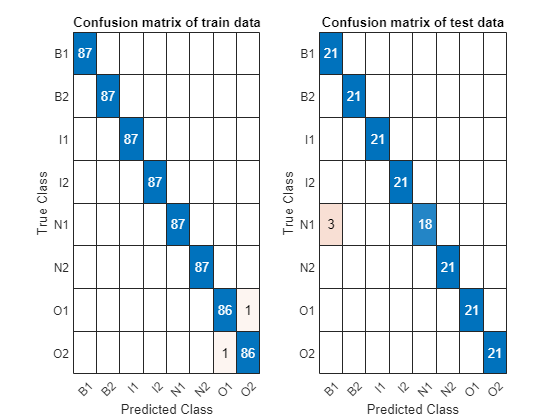

stcKNNloss = 0.0179

stcTrain    = table2array(normstaticFeatureTrain(:, 1:end-1));
stcTrainCls = table2array(normstaticFeatureTrain(:, end));
stcTest     = table2array(normstaticFeatureTest(:, 1:end-1));
stcTestCls  = table2array(normstaticFeatureTest(:, end));

stcKNNloss  = KNN(stcTrain, stcTrainCls, stcTest, stcTestCls)

2) SVM

ResubErr_SVM = 0

cvErr_SVM = 0.0043

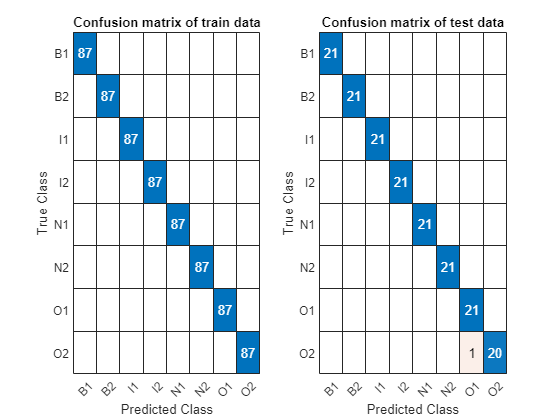

stcSVMloss = 0.0060

stcSVMloss = SVM(stcTrain, stcTrainCls, stcTest, stcTestCls)

3) Decision Tree

ResubErr_Tree = 0

cvErrTree = 0.0345

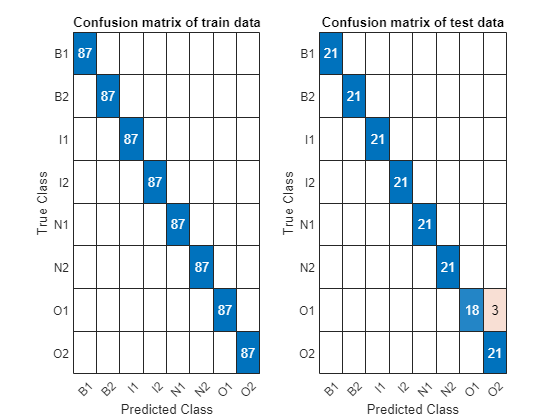

stcTREEloss = 0.0179

stcTREEloss = decisionTree(stcTrain, stcTrainCls, stcTest, stcTestCls)

### Classification : envelop feature

1) KNN

cvErrKNN = 0.0517

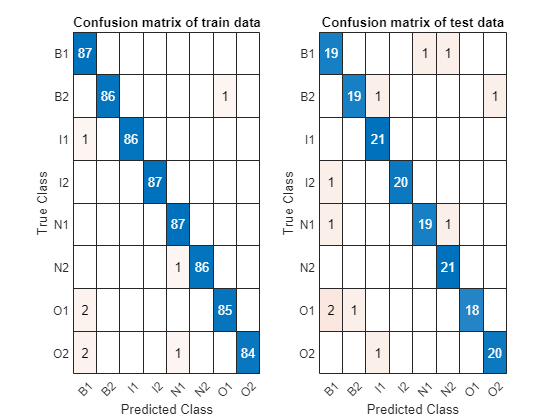

envKNNloss = 0.0655

envelopTrain = table2array(normenvelopFeatureTrain(:, 1:end-1));
envelopTrainCls = table2array(normenvelopFeatureTrain(:, end));
envelopTest = table2array(normenvelopFeatureTest(:, 1:end-1));
envelopTestCls = table2array(normenvelopFeatureTest(:, end));

envKNNloss = KNN(envelopTrain, envelopTrainCls, envelopTest, envelopTestCls)

2) SVM

ResubErr_SVM = 0.0445

cvErr_SVM = 0.1092

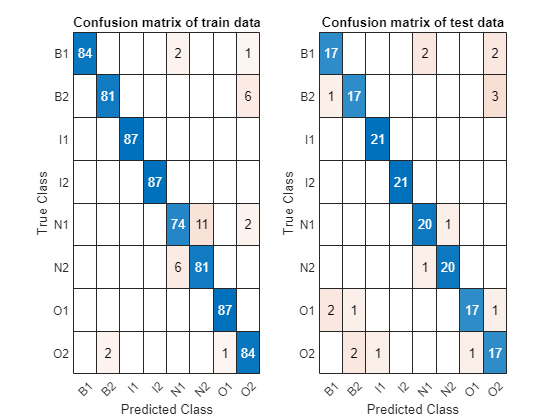

envSVMloss = 0.1071

envSVMloss = SVM(envelopTrain, envelopTrainCls, envelopTest, envelopTestCls)

3) Decision Tree

ResubErr_Tree = 0.0374

cvErrTree = 0.2701

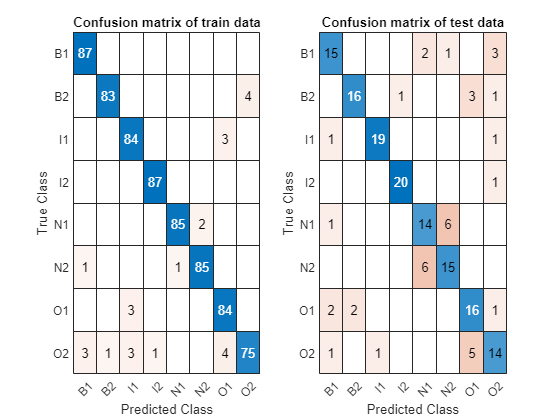

envTREEloss = 0.2321

envTREEloss = decisionTree(envelopTrain, envelopTrainCls, envelopTest, envelopTestCls)

### Classification : wavelet feature

1) KNN

cvErrKNN = 0.0259

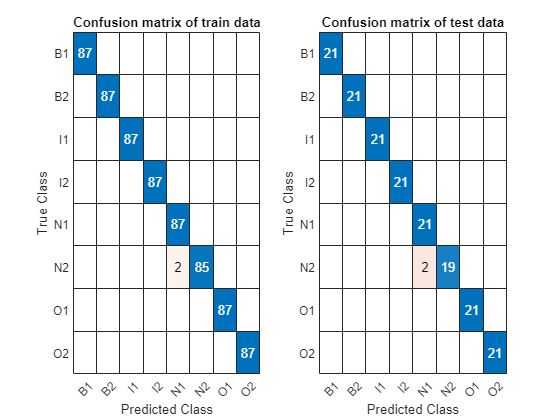

waveKNNloss = 0.0119

waveletTrain = table2array(normwaveletFeatureTrain(:, 1:end-1));
waveletTrainCls = table2array(normwaveletFeatureTrain(:, end));
waveletTest = table2array(normwaveletFeatureTest(:, 1:end-1));
waveletTestCls = table2array(normwaveletFeatureTest(:, end));

waveKNNloss = KNN(waveletTrain, waveletTrainCls, waveletTest, waveletTestCls)

2) SVM

ResubErr_SVM = 0.0201

cvErr_SVM = 0.0273

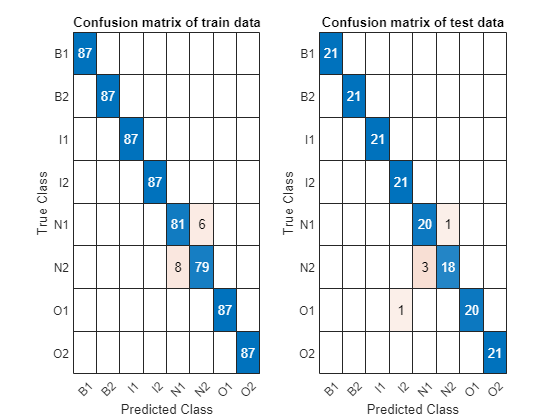

waveSVMloss = 0.0298

waveSVMloss = SVM(waveletTrain, waveletTrainCls, waveletTest, waveletTestCls)

3) Decision Tree

ResubErr_Tree = 0.0144

cvErrTree = 0.1020

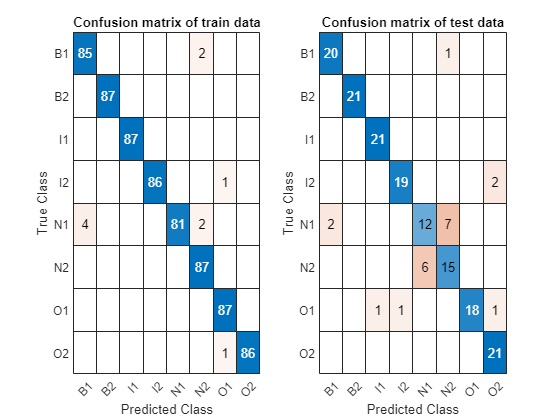

waveTREEloss = 0.1250

waveTREEloss = decisionTree(waveletTrain, waveletTrainCls, waveletTest, waveletTestCls)

### Classification : Global Pool

1) KNN

cvErrKNN = 0

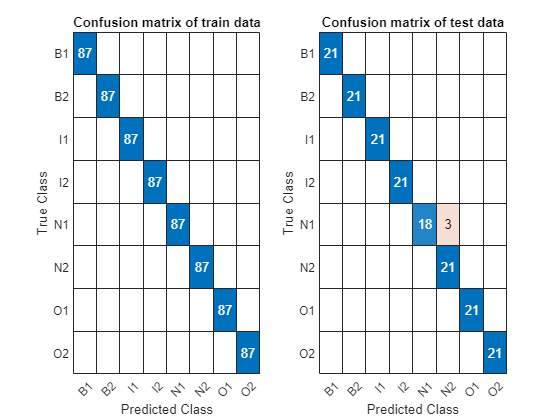

poolKNNloss = 0.0179

poolTrain = table2array(normglobalPoolTrain(:, 1:end-1));
poolTrainCls = table2array(normglobalPoolTrain(:, end));
poolTest = table2array(normglobalPoolTest(:, 1:end-1));
poolTestCls = table2array(normglobalPoolTest(:, end));

poolKNNloss = KNN(poolTrain, poolTrainCls, poolTest, poolTestCls)

2) SVM

ResubErr_SVM = 0

cvErr_SVM = 0

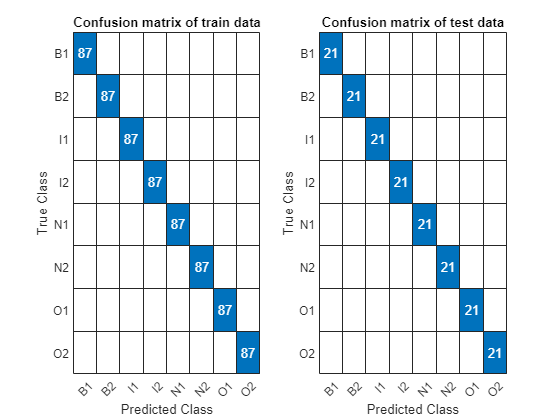

poolSVMloss = 0

poolSVMloss = SVM(poolTrain, poolTrainCls, poolTest, poolTestCls)

3) Decision Tree

ResubErr_Tree = 0.0014

cvErrTree = 0.0144

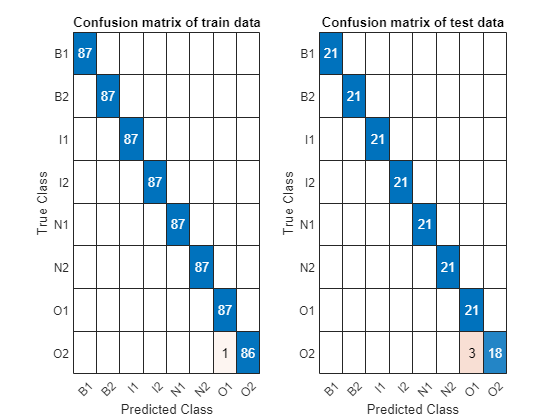

poolTREEloss = 0.0179

poolTREEloss = decisionTree(poolTrain, poolTrainCls, poolTest, poolTestCls)

## Feature reduction 

- Feature reduction in global pool

- Principal component analysis (PCA), Forward selection

globalPoolTrainPCA = globalPoolTrain(:,1:end-1);

[coeff, scores_train, ~, ~, explained, pcaCenter] = pca(table2array(globalPoolTrainPCA));

explain_standard = 0.95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 4

coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(globalPoolTrainPCA);
meanX = mean(table2array(globalPoolTrainPCA),1);

% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';

[ntest, ptest] = size(globalPoolTest(:,1:end));
mu = repmat(pcaCenter, ntest, 1);
global_test_pca = (table2array(globalPoolTest(:,1:end-1)) - mu)/coeff';

1) KNN

cvErrKNN = 0.0761

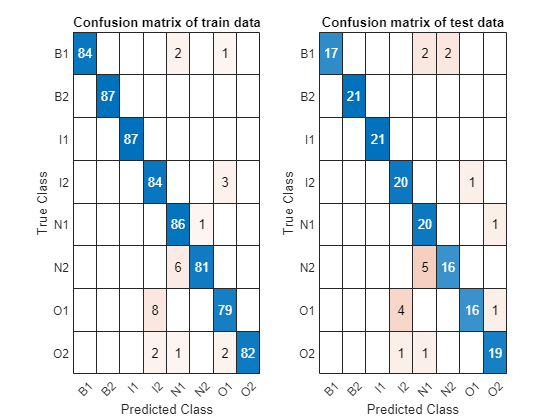

PCA_KNN_loss = 0.1071

PCA_KNN_loss = KNN(scores_train, poolTrainCls, global_test_pca, poolTestCls)

2) SVM

ResubErr_SVM = 0.0934

cvErr_SVM = 0.1092

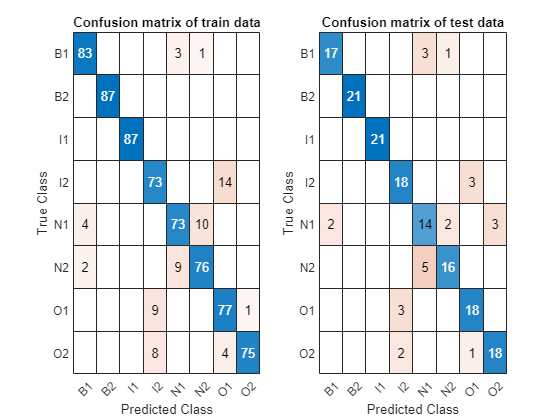

PCA_SVM_loss = 0.1488

PCA_SVM_loss = SVM(scores_train, poolTrainCls, global_test_pca, poolTestCls)

3) Decision Tree

ResubErr_Tree = 0.0402

cvErrTree = 0.1451

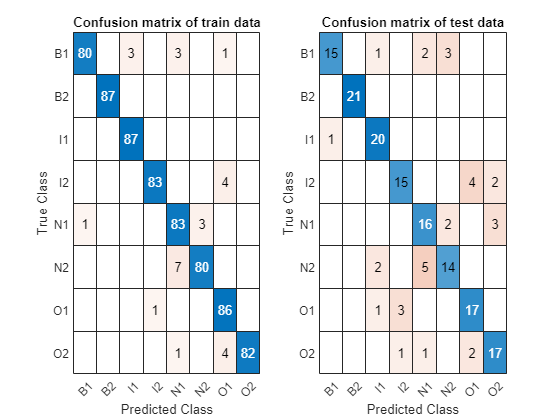

PCA_Tree_loss = 0.1964

PCA_Tree_loss = decisionTree(scores_train, poolTrainCls, global_test_pca, poolTestCls)

#### Backward selection

rng(0)
Y  = height(globalPoolTrainPCA);        
cv = cvpartition(Y,'KFold',3); 

lossfun = 'mincost';
opts = statset('Display','iter');

k = 1;
fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', 1),Xt,yt, 'Lossfun', lossfun);   
    
rng(0)

dir = 'backward';  
[inmodel, history] = sequentialfs(fun, table2array(globalPoolTrainPCA), poolTrainCls, 'cv', cv, 'options',opts, 'direction', dir)

Start backward sequential feature selection:
Initial columns included:  all
Columns that must be included:  none
Step 1, used initial columns, criterion value 0
Step 2, removed column 1, criterion value 0
Step 3, removed column 2, criterion value 0
Step 4, removed column 3, criterion value 0
Step 5, removed column 4, criterion value 0
Step 6, removed column 5, criterion value 0
Step 7, removed column 6, criterion value 0
Step 8, removed column 7, criterion value 0
Step 9, removed column 8, criterion value 0
Step 10, removed column 9, criterion value 0
Step 11, removed column 10, criterion value 0
Step 12, removed column 11, criterion value 0
Step 13, removed column 12, criterion value 0
Step 14, removed column 13, criterion value 0
Step 15, removed column 14, criterion value 0
Step 16, removed column 15, criterion value 0
Step 17, removed column 16, criterion value 0
Step 18, removed column 17, criterion value 0
Step 19, removed column 18, criterion value 0
Step 20, removed column 19, 

inmodel = 1×51 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   1   1   0   0   1   1   0   0   1   0   0   1   0   0   1   1   1   1   1   0   1   1   1


history = struct with fields:
      In: [34×51 logical]
    Crit: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]


select = find(inmodel);
global_Train_select = globalPoolTrain(:,select);
global_Test_select = globalPoolTest(:,select);

1) KNN

cvErrKNN = 0.0086

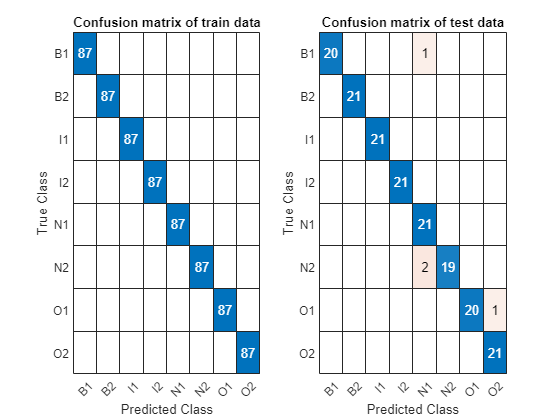

SFS_KNN_loss = 0.0238

SFS_KNN_loss = KNN(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

2) SVM

ResubErr_SVM = 0.0330

cvErr_SVM = 0.0460

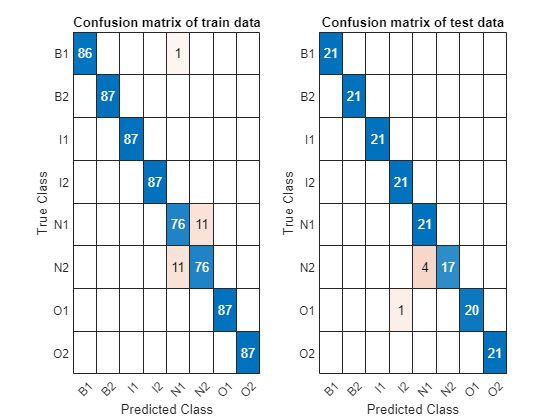

SFS_SVM_loss = 0.0298

SFS_SVM_loss = SVM(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

3) Decision Tree

ResubErr_Tree = 0.0115

cvErrTree = 0.1078

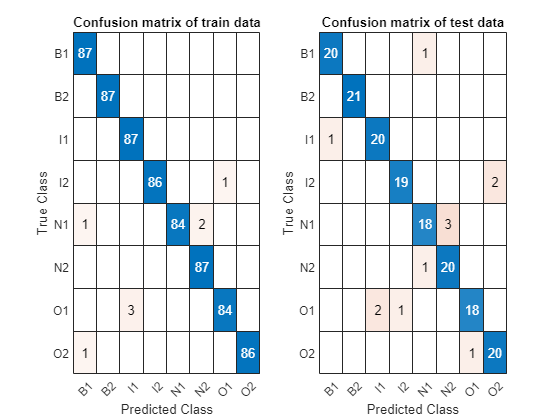

SFS_Tree_loss = 0.0714

SFS_Tree_loss = decisionTree(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

**- Table for comparing accuracy of each model**

**Compare objects : compare the each result of ( without selecting vs selecting )**

- Without selection

cmpLoss_without = [ stcKNNloss  stcSVMloss  stcTREEloss   ;
                    envKNNloss  envSVMloss  envTREEloss   ;
                    waveKNNloss waveSVMloss waveTREEloss  ;
                    poolKNNloss poolSVMloss poolTREEloss]

cmpLoss_without =     0.0179    0.0060    0.0179
    0.0655    0.1071    0.2321
    0.0119    0.0298    0.1250
    0.0179         0    0.0179


accuracy = round((1 - cmpLoss_without)*100, 2);

colName = ["KNN [%]", "SVM [%]", "Decision Tree [%]"];
rowName = ["Statistical feature", "Envelop feature", "Wavelet feature", "Global pool"];

withoutTbl = array2table(accuracy, "VariableNames", colName, "rownames", rowName)

withoutTbl = 4×3 table
                           KNN [%]    SVM [%]    Decision Tree [%]
                           _______    _______    _________________

    Statistical feature     98.21       99.4           98.21      
    Envelop feature         93.45      89.29           76.79      
    Wavelet feature         98.81      97.02            87.5      
    Global pool             98.21        100           98.21      


- With selection

loss_array_with = [PCA_KNN_loss PCA_SVM_loss PCA_Tree_loss ; ...
                   SFS_KNN_loss SFS_SVM_loss SFS_Tree_loss   ]

loss_array_with =     0.1071    0.1488    0.1964
    0.0238    0.0298    0.0714


accuracy_array_with = round((1 - loss_array_with) * 100,2);

rowName = ["PCA Pool" , "SFS Pool"];

accuracy_table_with = array2table(accuracy_array_with, "VariableNames", colName , "rownames", rowName)

accuracy_table_with = 2×3 table
                KNN [%]    SVM [%]    Decision Tree [%]
                _______    _______    _________________

    PCA Pool     89.29      85.12           80.36      
    SFS Pool     97.62      97.02           92.86      


## Discussion and analysis

#### 1) Feature extraction

            All data in this lab was appropriately augmented beforehand. One distinguishing factor compared to previous labs is that the number of classes for which features needed to be extracted has increased. Previously, multiple feature extractions could be performed for Ball fault, Outer fault, Inner fault, and Normal classes. However, in this case, elements related to alignment or misalignment were included for the aforementioned classes, resulting in the extraction of features for a total of 8 classes. A test set was applied accordingly. The train set consisted of 120000 x 87 augmented data, and feature extraction was conducted for each column. Statistical features, frequency features, envelop features, wavelet features, and others were used as the extracted features. For each class, 87 individual columns were analyzed, resulting in the creation of 696 x 57 feature tables when analyzed for all classes according to Global Pool standards. Later, the test set was also subjected to feature extraction in the same way to evaluate the performance of the trained models using KNN, SVM, and Decision Tree techniques.

#### 2) Feature without selection / with selection / Backward selection

            The model generated using all features without feature selection showed relatively high classification performance on the test set, except for the Decision Tree for Envelop. When selecting features with relatively high performance through Principal Component Analysis and creating a model, a relatively lower performance degradation occurred compared to the aforementioned global pool, but still showed high predictive performance. This technique selects features with high performance through processes such as selecting eigen vectors that maximize variance while minimizing error, enabling dimensionality reduction (feature reduction). However, as confirmed by the results of the previous lab, it is not guaranteed that performance degradation will be avoided accordingly. Initially, forward selection was attempted but showed low performance. Thus, when backward selection was applied, a significantly improved performance was observed, which requires further analysis.

- The difference between forward selection and backward selection: 

1) Forward selection is a method of creating a model by starting with an empty model and adding the most important feature at each stage. This method evaluates whether the model's performance improves as variables are added and stops the process if there is no improvement or the improvement is minimal.

2) Backward selection, on the other hand, is a method of creating a model by starting with a model that includes all features and removing the least important feature at each stage. Similarly, the process is stopped if there is no improvement or the improvement is minimal when removing variables.

Forward selection starts with a simpler model, important features may not be captured at the initial stage. This can result in low model performance. In contrast, because backward selection starts with a model that includes all features, which already includes important features, better performance can be obtained.